    contraction_counter = 901;
    z_grid_points = z_grid_points_all(:, :, :, contraction_counter);
    r_grid_points = r_grid_points_all(:, :, :, contraction_counter);
    L1 = L1_vector(contraction_counter);
    L = L_vector(contraction_counter);
    Contraction = contraction_vector(contraction_counter)

Contraction = 95

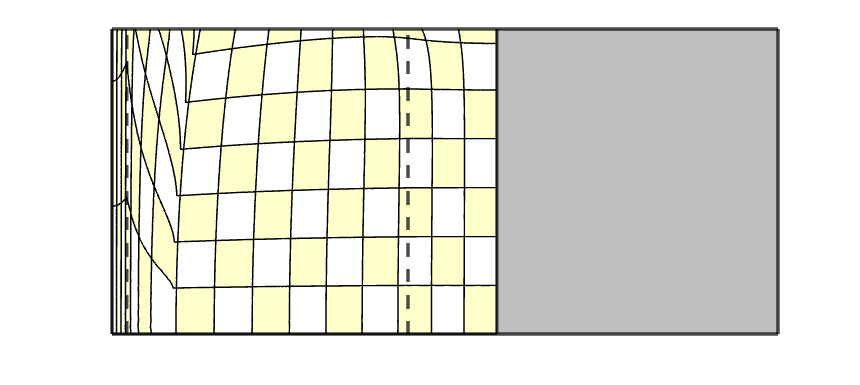


    xlim([0, max_L])
    ylim([0, R])
    hold on
    for r_counter = 1:r_grids
        for z_counter = 1:z_grids
            plot(z_grid_points(:, r_counter, z_counter), r_grid_points(:, r_counter, z_counter), 'k', 'LineWidth', 1)
            if mod(r_counter + z_counter, 2) == 0
                fill(z_grid_points(:, r_counter, z_counter), r_grid_points(:, r_counter, z_counter), [1, 1, 1])
            else
                fill(z_grid_points(:, r_counter, z_counter), r_grid_points(:, r_counter, z_counter), [1, 1, 0.8])
            end
        end
    end    

    x0=10;
    y0=10;
    width=308*(L_vector(1)/max_L)*(z_grids/r_grids);
    height=308;
    set(gcf,'position',[x0,y0,width,height])
    xline(L1, '--k', 'LineWidth', 2)
    xline(L2, '--k', 'LineWidth', 2)
    xline(0, 'k', 'LineWidth', 2)
    xline(L, 'k', 'LineWidth', 2)
    xline(max_L, 'k', 'LineWidth', 2)
    yline(0, 'k', 'LineWidth', 2)
    yline(R, 'k', 'LineWidth', 2)
    fill([L, max_L, max_L, L], [0, 0, R, R], [0.75, 0.75, 0.75], 'LineStyle', 'none')
    set(gca, 'visible', 'off');
    hold off